numSubframes = 10;        % Number of subframes
gnbNumPRB = 52;           % Size of 5G carrier in number of PRBs (1...275)
enbNumPRB = 25;           % Size of LTE carrier in number of PRBs
enbNumCRSPorts = 2;      % Number of LTE CRS ports
enbVShift = 0;           % LTE shifting value v-Shift
enbCarrierFrequency = 0; % LTE carrier offset to NR point A, in units of 15 kHz subcarriers (0...16383)
rng("default");
enb = getLTEConfig(enbNumPRB,enbNumCRSPorts,enbVShift,enbCarrierFrequency,numSubframes);
gnb = nrCarrierConfig;
gnb.NSizeGrid = gnbNumPRB;
disp(gnb)

  nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10



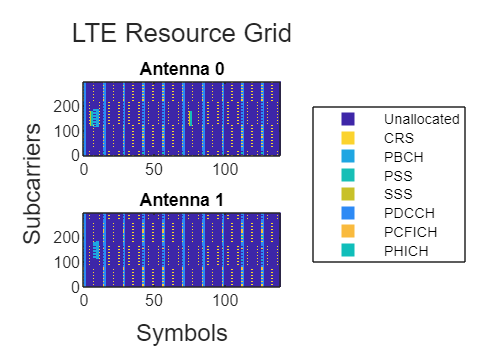

pdsch = nrPDSCHConfig;
pdsch.PRBSet = 0:gnb.NSizeGrid-1;      % Full-band allocation
pdsch.SymbolAllocation = [3 11];       % Full-slot allocation, starting from symbol 3
pdsch.MappingType = "A";               % PDSCH mapping type A
pdsch.DMRS.DMRSTypeAPosition = 3;      % First DM-RS in symbol 3 for PDSCH mapping type A
pdsch.DMRS.DMRSAdditionalPosition = 1; % Additional DM-RS position
if (pdsch.MappingType == "A") && ...
        (pdsch.DMRS.DMRSAdditionalPosition == 1) && ...
        (pdsch.DMRS.DMRSTypeAPosition == 3)
    pdsch.DMRS.CustomSymbolSet = [3 12];
end
pdsch.ReservedRE = getReservedRE(enbNumPRB,enbNumCRSPorts,enbVShift,enbCarrierFrequency,gnb);
pdsch.ReservedPRB = getReservedPRB(enb,gnb);
pdschPower = 15;     % PDSCH power scaling in dB
pdschDMRSPower = 18; % PDSCH DM-RS power scaling in dB[enbWave,enbGrid] = lteRMCDLTool(enb,[1;0;0;1]);
enbInfo = lteOFDMInfo(enb);
enbChannelNames = ["CRS","PBCH","PSS","SSS","PDCCH","PCFICH","PHICH"];
plotResourceGrid(enb,enbGrid,numSubframes,enbChannelNames);

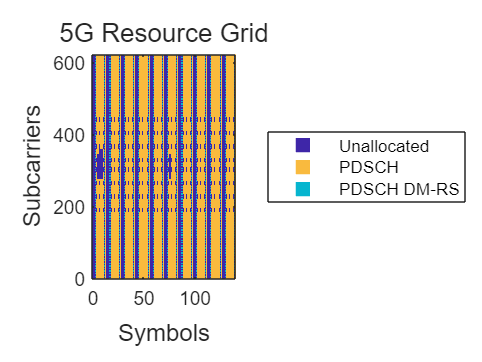

numSlots = numSubframes*gnb.SlotsPerSubframe;
gnbGrid = [];
for nslot = 0:numSlots-1

    % Update the carrier slot number and create an empty resource grid for
    % the current slot
    gnb.NSlot = nslot;
    gridSlot = nrResourceGrid(gnb,pdsch.NumLayers);

    % Get the PDSCH and PDSCH DM-RS indices and symbols
    [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(gnb,pdsch);
    cw = randi([0 1],pdschIndicesInfo.G,1);
    pdschSymbols = nrPDSCH(gnb,pdsch,cw) * db2mag(pdschPower);
    pdschDMRSIndices = nrPDSCHDMRSIndices(gnb,pdsch);
    pdschDMRSSymbols = nrPDSCHDMRS(gnb,pdsch) * db2mag(pdschDMRSPower);

    % Place the symbols in the grid
    gridSlot(pdschIndices) = pdschSymbols;
    gridSlot(pdschDMRSIndices) = pdschDMRSSymbols;

    % Append the resource grid for the current slot to the overall resource
    % grid
    gnbGrid = cat(2,gnbGrid,gridSlot);

end
gnbChannelNames = ["PDSCH","PDSCH DM-RS"];
plotResourceGrid(struct("gnb",gnb,"pdsch",pdsch),gnbGrid,numSubframes,gnbChannelNames);

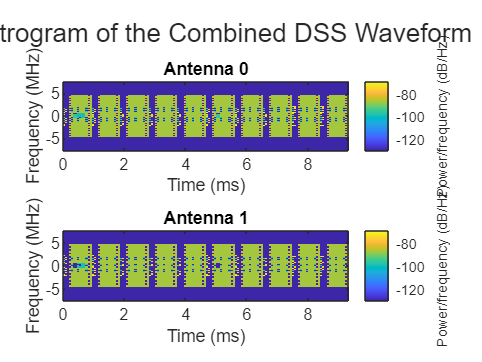

[gnbWave,gnbInfo] = nrOFDMModulate(gnb,gnbGrid,Windowing=0);
enbfotx = comm.PhaseFrequencyOffset;
enbfotx.SampleRate = enbInfo.SamplingRate;
enbfotx.FrequencyOffset = enbCarrierFrequency*15e3; % Hz
enbWave = enbfotx(enbWave);
enbSR = enbInfo.SamplingRate;
gnbSR = gnbInfo.SampleRate;
if gnbSR >= enbSR
    enbWave = resample(enbWave,gnbSR,enbSR);
    ofdmInfo = gnbInfo;
else
    gnbWave = resample(gnbWave,enbSR,gnbSR);
    ofdmInfo = enbInfo;
end
wave = enbWave + gnbWave;
plotDSSSpectrogram(wave,ofdmInfo,enbSR,gnbSR,numSubframes);

function enb = getLTEConfig(numPRB,numCRSPorts,vShift,carrierFrequency,numSubframes)
    % Generate the cell-wide configuration for LTE, given the number of
    % PRBs, the number of CRS ports, the shifting value v-Shift for the LTE
    % CRS, and the carrier frequency offset from point A.

    % Define the LTE configuration
    enb = struct();
    enb.NDLRB = numPRB;
    enb.CellRefP = numCRSPorts;
    enb.NCellID = vShift;
    enb.CyclicPrefix = "Normal";
    enb.CFI = 2;
    enb.Ng = "Sixth";
    enb.PHICHDuration = "Normal";
    enb.NFrame = 0;
    enb.NSubframe = 0;
    enb.TotSubframes = numSubframes;
    enb.DuplexMode = "FDD";
    if numCRSPorts>1
        enb.PDSCH.TxScheme = "SpatialMux";
    end
    enb.CarrierFrequency = carrierFrequency;

    % Define the power scaling of LTE signals and channels.
    % These values are chosen solely to ease the visualization of each
    % channel and signal in the spectrogram view.
    enb.PDSCH.PDCCHPower = 24;
    enb.PCFICHPower = 12;
    enb.PHICHPower = 30;
    % To make sure that the LTE waveform contains PDCCH but not PDSCH, set
    % the PDSCH power resource element allocation so that the content of
    % the PDSCH does not affect the LTE waveform
    enb.PDSCH.Rho = -inf;
end

function ind = getReservedRE(numPRB,numCRSPorts,vShift,carrierFrequency,gnb)
    % Compute the REs used by the LTE CRS that the 5G PDSCH needs to
    % rate-match around.

    % Get the LTE configuration for the rate-matching around the CRS
    enb = struct();
    enb.NDLRB = numPRB;
    enb.CellRefP = numCRSPorts;
    enb.NCellID = vShift;
    enb.CarrierFrequency = carrierFrequency;
    enb.CyclicPrefix = "Normal";
    enb.DuplexMode = "FDD";

    % Get the RE indices for the CRS
    ind = getLTEREIndices(enb,gnb,"CRS");
end

function prbs = getReservedPRB(enb,gnb)
    % Compute the physical resource blocks used by the LTE PBCH, PSS, and
    % SSS that the 5G PDSCH needs to rate-match around.

    % Initialize empty nrPDSCHReservedConfig objects to store the reserved
    % PRBs. The example defines two objects because the periodicity of the
    % PBCH is different from that of the PSS and SSS.
    prbs = {nrPDSCHReservedConfig,nrPDSCHReservedConfig};

    % Compute the 5G BWP grid size
    gnbSize = size(nrResourceGrid(gnb));

    % Get the RE indices for the PBCH and convert them to subscript
    pbchInd = getLTEREIndices(enb,gnb,"PBCH");
    [pbchREInd,pbchSymbInd] = ind2sub(gnbSize,pbchInd);

    % Store the reserved PRBs for the LTE PBCH. Set the period considering
    % that the PBCH is transmitted in subframe 0 of each frame.
    prbInd = unique(floor(pbchREInd/12)); % 0-based PRBs associated to the RE indices
    prbs{1}.PRBSet = prbInd;
    prbs{1}.SymbolSet = unique(pbchSymbInd-1); % 0-based
    prbs{1}.Period = 10*gnb.SlotsPerSubframe;

    % Get the RE indices for the PSS and SSS and convert them to subscript
    ssInd = getLTEREIndices(enb,gnb,["PSS","SSS"]);
    [ssREInd,ssSymbInd] = ind2sub(gnbSize,ssInd);

    % Store the reserved PRBs for the LTE synchronization signals PSS and
    % SSS. Set the period considering that the PSS and SSS are transmitted
    % in subframes 0 and 5 of each frame.
    prbInd = unique(floor(ssREInd/12)); % 0-based PRBs associated to the RE indices
    prbs{2}.PRBSet = prbInd;
    prbs{2}.SymbolSet = unique(ssSymbInd-1); % 0-based
    prbs{2}.Period = 5*gnb.SlotsPerSubframe;
end

function ind = getLTEREIndices(enb,gnb,signalName)
    % Compute the REs used by LTE always-on signals (CRS, PBCH, PSS, and
    % SSS) that the 5G PDSCH needs to rate-match around.

    % enb frequency indices 'enbf' in terms of 15 kHz subcarrier spacing
    enbSize = lteResourceGridSize(enb);
    enbK = enbSize(1);
    enbf = [-enbK/2:-1 1:enbK/2].' + enb.CarrierFrequency;

    % gnb frequency indices 'gnbf' in terms of 15 kHz subcarrier spacing
    gnbSize = size(nrResourceGrid(gnb));
    gnbK = gnbSize(1);
    gnbf = (-gnbK/2:(gnbK/2 - 1)).';
    gnbf = gnbf(gnb.NStartGrid*12 + (1:gnbK));

    % Compute the CRS indices
    crsIndices = [];
    if any(signalName=="CRS")
        crsIndices = lteCellRSIndices(enb,"sub");
    end
    % Compute the PBCH indices
    pbchIndices = [];
    if any(signalName=="PBCH")
        pbchIndices = ltePBCHIndices(enb,"sub");
    end
    % Compute the PSS indices
    pssIndices = [];
    if any(signalName=="PSS")
        pssIndices = ltePSSIndices(enb,0,"sub");
    end
    % Compute the SSS indices
    sssIndices = [];
    if any(signalName=="SSS")
        sssIndices = lteSSSIndices(enb,0,"sub");
    end
    % Create the list of all indices
    indTot = [crsIndices; pbchIndices; pssIndices; sssIndices];
    enbk = indTot(:,1);
    enbl = indTot(:,2);

    enbf = enbf(enbk);

    gnbk = arrayfun(@(x)find(gnbf==x),enbf,UniformOutput=false);
    z = cellfun(@isempty,gnbk);
    gnbk = cat(1,zeros(0,1),gnbk{:});

    gnbl = enbl;
    gnbl(z) = [];

    ind = sub2ind(gnbSize,gnbk,gnbl);
    ind = ind - 1; % 1-based to 0-based
end

function plotResourceGrid(in,grid,numSubframes,chNames)
    % Plot the resource grid for each antenna.

    if isfield(in,"CellRefP") % LTE
        isLTE = 1;
        nsf = numSubframes;
        enb = in;
        numPorts = enb.CellRefP;
    else % 5G
        isLTE = 0;
        gnb = in.gnb;
        pdsch = in.pdsch;
        nsf = numSubframes* gnb.SlotsPerSubframe;
        numPorts = pdsch.NumLayers;
    end
    chNames = ["Unallocated" chNames];

    % Define channel power levels
    chplevel.Unallocated = 0;   % Unallocated REs
    chplevel.CRS = 0.9;         % LTE CRS
    chplevel.PBCH = 0.39;       % LTE PBCH
    chplevel.PSS = 0.51;        % LTE PSS
    chplevel.SSS = 0.75;        % LTE SSS
    chplevel.PDCCH = 0.3;       % LTE PDCCH
    chplevel.PCFICH = 0.83;     % LTE PCFICH
    chplevel.PHICH = 0.5;       % LTE PHICH
    chplevel.PDSCH = 0.83;      % 5G PDSCH
    chplevel.PDSCH_DMRS = 0.45; % 5G PDSCH DM-RS
    
    % Generate the resource grid for plotting
    rbGrid = [];
    gridSize = size(grid);
    gridSize(2) = gridSize(2)/nsf; % Length of a single subframe or slot
    for ns = 0:nsf-1 % Loop over each LTE subframe or 5G slot
        % Initialize an empty grid for the current subframe or slot
        rbGridS = zeros(gridSize);
    
        % Populate the grid
        if isLTE
            enb.NSubframe = mod(ns,10);

            rbGridS(lteCellRSIndices(enb)) = chplevel.CRS;
            rbGridS(ltePSSIndices(enb)) = chplevel.PSS;
            rbGridS(lteSSSIndices(enb)) = chplevel.SSS;
            rbGridS(ltePBCHIndices(enb)) = chplevel.PBCH;
            rbGridS(ltePCFICHIndices(enb)) = chplevel.PCFICH;
            rbGridS(ltePHICHIndices(enb)) = chplevel.PHICH;
            rbGridS(ltePDCCHIndices(enb)) = chplevel.PDCCH;

        else % 5G
            gnb.NSlot = mod(ns,10);

            rbGridS(nrPDSCHIndices(gnb,pdsch)) = chplevel.PDSCH;
            rbGridS(nrPDSCHDMRSIndices(gnb,pdsch)) = chplevel.PDSCH_DMRS;
        end

        % Append the resource grid for the current subframe or slot to the
        % overall resource grid
        rbGrid = cat(2,rbGrid,rbGridS);
    end
    
    % Define the colormap and the scaling needed for the plot
    cmap = parula(256);
    chpval = struct2cell(chplevel);
    cscaling = length(cmap);
    fnames = strrep(fieldnames(chplevel),"_"," ");
    fnames = strrep(fnames,"DMRS","DM-RS");
    chpval = chpval(contains(fnames,chNames));
    clevels = floor(cscaling*[chpval{:}]);
    
    % Define the plot title
    if isLTE
        figTitle = "LTE Resource Grid";
    else
        figTitle = "5G Resource Grid";
    end
    plotTitle = "Antenna ";

    % Define the axes limits for the plot to be 0-based
    minX = 0;
    maxX = size(rbGrid,2)-1;
    minY = 0;
    maxY = size(rbGrid,1)-1;

    % Plot the resource grid for each port or layer
    fh = figure;
    t = tiledlayout(fh,"flow",TileSpacing="Compact");
    for idx = 1:numPorts
        nexttile;
        ax = gca;
        img = image(ax,cscaling*abs(rbGrid(:,:,idx)));
        img.XData = minX:maxX; % 0-based symbol number
        img.YData = minY:maxY; % 0-based subcarrier number
        axis(ax,[minX-0.5 maxX+0.5 minY-0.5 maxY+0.5]);
        axis(ax,"xy");
        if numPorts>1
            title(ax,plotTitle+num2str(idx-1)); % 0-based antenna number
        end
        colormap(ax,cmap);
    end
    title(t,figTitle);
    xlabel(t,"Symbols");
    ylabel(t,"Subcarriers");
    
    % Create the legend
    N = length(clevels);
    p = struct(Marker="s",LineStyle="none",MarkerSize=8,LineWidth=1.25);
    L = line(ax,NaN(N),NaN(N),p); % Generate markers
    % Index the color map and associate the selected colors with the markers
    c = mat2cell([cmap(1,:);cmap(clevels(2:end),:)],ones(1,N),3);
    set(L,{"color"},c); %#ok<STRSCALR> 
    set(L,{"MarkerFaceColor"},c); %#ok<STRSCALR> 
    lg = legend(ax,chNames{:});
    lg.Layout.Tile = "East";
end

function plotDSSSpectrogram(wave,ofdmInfo,enbSR,gnbSR,numSubframes)
    % Plot the spectrogram of the combined waveform.

    % To minimize the artifacts shown in the spectrogram and due to out of
    % band leakage of the resampled waveform, adjust the waveform to
    % consider the filter response.
    cpLengths = double(ofdmInfo.CyclicPrefixLengths);
    OSR = max(enbSR/gnbSR,gnbSR/enbSR);
    n = min(10,floor(max(cpLengths)/(2*OSR)));
    order = 2*n*OSR; % Order of the filter used during resampling
    wave = circshift(wave,order/2);

    fh = figure;
    t = tiledlayout(fh,"flow",TileSpacing="Compact");
    % Compute the cyclic prefixes to remove from the waveform for each
    % subframe.
    nfft = double(ofdmInfo.Nfft);
    if isfield(ofdmInfo,'SampleRate')
        sampleRate = ofdmInfo.SampleRate;
    else
        sampleRate = ofdmInfo.SamplingRate;
    end
    symbolLengths = nfft+cpLengths;
    cpidxs = arrayfun(@(x,y)(x+(1:y)),cumsum([0 symbolLengths(1:end-1)]),cpLengths,UniformOutput=false);
    cpidxs = [cpidxs{:}];
    sfWaveLength = sampleRate/1000;
    
    % Loop over each antenna
    for idx = 1:size(wave,2)
        nexttile;
        txWaveNoCP = [];
        for nsf = 1:numSubframes
            waveNoCP = wave(1+(nsf-1)*sfWaveLength:nsf*sfWaveLength,idx);
            waveNoCP(cpidxs) = []; % Remove the cyclic prefix in this subframe
            txWaveNoCP = cat(1,txWaveNoCP, waveNoCP);
        end
        spectrogram(txWaveNoCP,ones(nfft,1),0,nfft,"centered",sampleRate,"yaxis",MinThreshold=-130);
        title(['Antenna ' num2str(idx-1)]); % 0-based antenna number
    end
    title(t,"Spectrogram of the Combined DSS Waveform");
end